% 连续过程标签
data_all = readtable('D:\桌面\论文材料\RAMAN第二次实验\第四次\离线标签.xlsx');
% data_all = removevars(data_all, {'x____h_', 'Var7'});
data_all = table2array(data_all)

data_all =    10.0599    0.2031         0
    9.6691    0.3364         0
    8.6117    1.1003         0
    7.1870    1.6803         0
    5.6255    4.8211         0
    4.0977    7.6517         0
    2.7229    9.9005         0
    1.5768   11.5897         0
    0.6994   12.9427         0
    0.1015   14.3015         0


data= data_all

data =    10.0599    0.2031         0
    9.6691    0.3364         0
    8.6117    1.1003         0
    7.1870    1.6803         0
    5.6255    4.8211         0
    4.0977    7.6517         0
    2.7229    9.9005         0
    1.5768   11.5897         0
    0.6994   12.9427         0
    0.1015   14.3015         0


data_porcelabel = data_all(:,1:3)

data_porcelabel =    10.0599    0.2031         0
    9.6691    0.3364         0
    8.6117    1.1003         0
    7.1870    1.6803         0
    5.6255    4.8211         0
    4.0977    7.6517         0
    2.7229    9.9005         0
    1.5768   11.5897         0
    0.6994   12.9427         0
    0.1015   14.3015         0


n_substance=1

n_substance = 1

data_spc = readtable('D:\桌面\论文材料\RAMAN第二次实验\第四次\预处理后的光谱.xlsx');
%data_spc = removevars(data_spc, {'Var1'});
data_spc = table2array(data_spc)

data_spc =    -0.1670   -0.1086   -0.1432   -0.1861   -0.2066   -0.2029   -0.1856   -0.1675   -0.1585   -0.1634   -0.1815   -0.2079   -0.2353   -0.2550   -0.2595   -0.2429   -0.2018   -0.1359   -0.0475    0.0585    0.1755    0.2961    0.4126    0.5180    0.6066    0.6745    0.7223    0.7452    0.7459    0.7275    0.6960    0.6566    0.6143    0.5750    0.5405    0.5111    0.4870    0.4664    0.4467    0.4254    0.4006    0.3726    0.3438    0.3167    0.2927    0.2750    0.2610    0.2482    0.2355    0.2239
   -0.1846   -0.1300   -0.1647   -0.2030   -0.2169   -0.2077   -0.1880   -0.1713   -0.1666   -0.1770   -0.1998   -0.2285   -0.2543   -0.2681   -0.2626   -0.2327   -0.1765   -0.0952    0.0073    0.1247    0.2496    0.3742    0.4911    0.5939    0.6779    0.7405    0.7843    0.8056    0.8073    0.7919    0.7631    0.7267    0.6896    0.6518    0.6171    0.5843    0.5530    0.5218    0.4889    0.4546    0.4166    0.3787    0.3401    0.3046    0.2761    0.2530    0.2353    0.2207    0.20

x_axis = 1:1:32

x_axis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


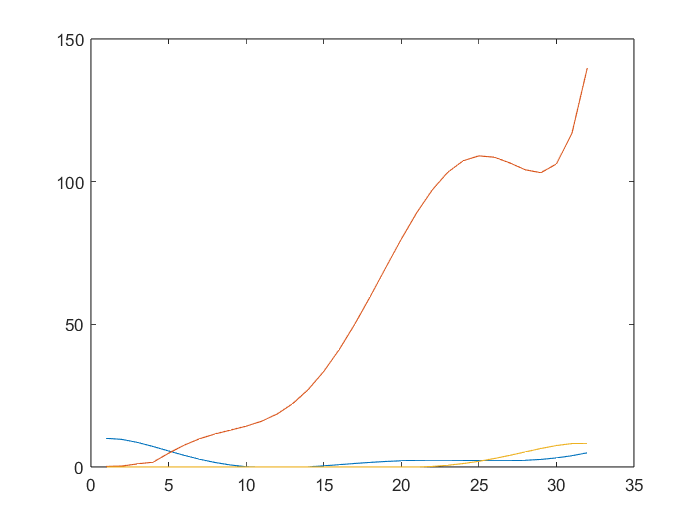

plot(data_porcelabel)

x_fit = linspace(1, 32, 697)

x_fit =     1.0000    1.0445    1.0891    1.1336    1.1782    1.2227    1.2672    1.3118    1.3563    1.4009    1.4454    1.4899    1.5345    1.5790    1.6236    1.6681    1.7126    1.7572    1.8017    1.8463    1.8908    1.9353    1.9799    2.0244    2.0690    2.1135    2.1580    2.2026    2.2471    2.2917    2.3362    2.3807    2.4253    2.4698    2.5144    2.5589    2.6034    2.6480    2.6925    2.7371    2.7816    2.8261    2.8707    2.9152    2.9598    3.0043    3.0489    3.0934    3.1379    3.1825


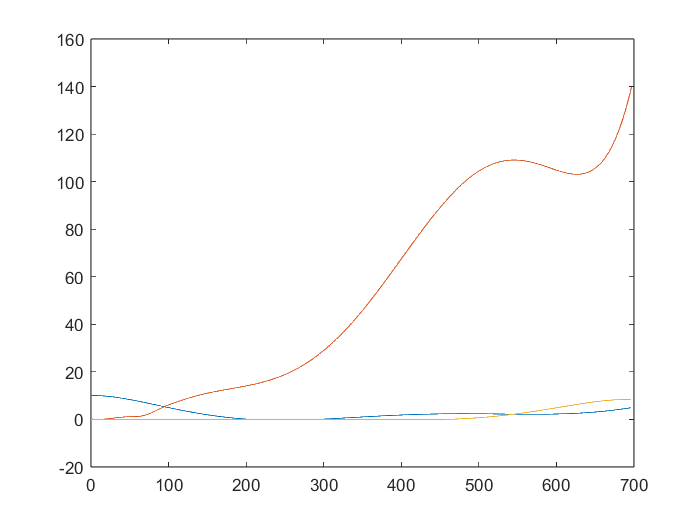

% 对每一列进行插值
nCols = size(data_porcelabel, 2);
y_porcess = zeros(length(x_fit), nCols);
for i = 1:nCols
    y_porcess(:, i) = interp1(x_axis, data_porcelabel(:, i), x_fit, 'spline');
end
plot(y_porcess)

y_porcess=abs(y_porcess)

y_porcess =    10.0599    0.2031         0
   10.0610    0.1648    0.0000
   10.0602    0.1320    0.0000
   10.0575    0.1045    0.0000
   10.0530    0.0820    0.0000
   10.0466    0.0644    0.0000
   10.0385    0.0515    0.0000
   10.0285    0.0430    0.0000
   10.0168    0.0388    0.0000
   10.0034    0.0387    0.0000


% 输出表格
y_merge = horzcat(y_porcess,  data_spc);
xlswrite('D:\桌面\论文材料\RAMAN第二次实验\第四次\插值过程标签光谱.xlsx', y_merge);
